# EPR UK 1000

clear; close all; clc;

## Dane:

ThermalPower = 4500e6;          %   [W]    moc cieplna reaktora
ActiveHeight = 4200/1000;       %   [m]    wysokość aktywnej części rdzenia
Pressure = 155;                 %   [bar]
NAssembly = 241;                %   [-]    liczba kaset paliwowych
NRods = 265;                    %   [-]    liczba prętów paliwowych w kasecie
TempInput = 295.6;              %   [°C]   temperatura wlotowa
WaterFlux = 75643000/3600;      %   [kg/s] strumień masy wody chłodzącej
AssemblyPitch = 214/1000;       %   [m]    skok siatki kaset
RodDiameter = 9.5/1000;         %   [m]    średnica pręta paliwowego
RodPitch = 112.6/1000;          %   [m]    skok siatki prętów w kasecie
UraniumMass = 527.5 * NAssembly;%   [kg]   masa materiału rozszczepialnego w rdzeniu
ExLength = 50/1000;             %   [m]    Długość ekstrapolacji

# Do zmianyyyyy!!!!

Pxy = 1.438;                    %   [-]    Wsp. promieniowy nierównomierności rozkładu      DO ZMIANY!!!!!!!!!!!!!

Te chyba nie są potrzebne

NeutronVelocity = 2200;         %   [m/s]  prędkość neutronów termicznych
SigmaU235 = 505e-24 * 1e-4;     %   [m]    efektywny mikroskopowy przekrój czynny na rozszczepienie dla neutronów termicznych dla U235
N_U235 = 1.3457e+20 * 1e6;      %   [1/m3] gęstość liczbowa/atomowa materiału rozszczepialnego
w_tot = 200 * 1e6 * 1.602e-19;  %   [J]    energia na jedno roszczepienie

## 1. Liniowa gęstość mocy

Liczba reakcji:

w_f = 0.95 * w_tot;                             %   [J]    odzyskiwalna energia
NReactions = ThermalPower / w_f;                %   [1/s]  liczba reakcji w rdzeniu

Objętość rdzenia:

AssemblyArea = AssemblyPitch^2;                         %   [m2]    powierzchnia przekroju poprzecznego jednej kasety
CoreVolume = AssemblyArea * ActiveHeight * NAssembly;   %   [m3]    objętość rdzenia

Szybkość reakcji:

Rf = NReactions * CoreVolume;                   %   [1/m3/s]    średnia szybkość reakcji w rdzeniu
Phi = Rf / (SigmaU235 * N_U235);                %   [1/m2/s]    średni strumień neutronów

Gęstość mocy rdzenia (objętościowa):

PowerDensityVol = ThermalPower / CoreVolume;    %   [W/m3]  średnia objętościowa gęstość mocy

Gęstość mocy rdzenia (właściwa):

PowerDensitySpec = ThermalPower / UraniumMass;  %   [W/kgU]     średnia właściwa gęstość mocy

Moc kasety:

AssemblyPower = ThermalPower / NAssembly;       %   [W]     średnia moc kasety

Moc pręta:

RodPower = AssemblyPower / NRods;               %   [W]     średnia moc pręta

Moc liniowa:

LengthTotal = ActiveHeight * NRods * NAssembly; %   [m]     całkowita długość prętów
LinHeatRate = ThermalPower / LengthTotal        %   [W/m]   średnia moc liniowa

LinHeatRate = 1.6776e+04

## 1. Rozkład mocy wzdłuż kanału

ExHeight = ActiveHeight + 2 * ExLength;                                                                 %   [m]     wysokość rdzenia + 2 długości ekstrapolacji
ChannelPower = ThermalPower / (NAssembly * NRods);                                                      %   [W]     średnia moc kanału
AvgChannelPowerMax = pi * ChannelPower / (ExHeight * 2 * sin((pi * ActiveHeight) / (2 * ExHeight)));    %   [W/m]     maksymalna moc dla średniego kanału
HotChannelPowerMax = AvgChannelPowerMax * Pxy;                                                          %   [W/m]     maksymalna moc dla gorącego kanału

rozkład mocy w kanałach:

z = linspace(-ActiveHeight/2, ActiveHeight/2, 100);
AvgChannelPower =  AvgChannelPowerMax * cos(pi * z / ExHeight);     %   rozkład mocy liniowej średniego kanału
HotChannelPower =  HotChannelPowerMax * cos(pi * z / ExHeight);     %   rozkład mocy liniowej gorącego kanału

Wykres:

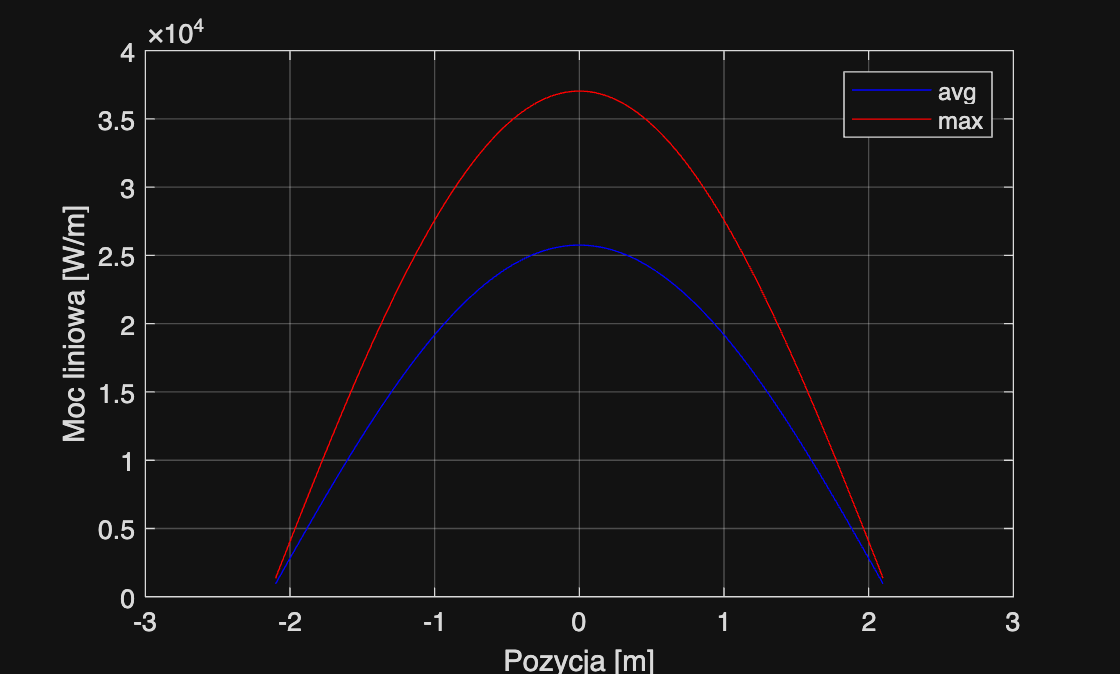

figure(1); grid on; box on; hold on;
ylabel("Moc liniowa [W/m]")
xlabel("Pozycja [m]")
plot(z, AvgChannelPower, "b-")
plot(z, HotChannelPower, "r-")
legend('avg', 'max')

## 2. Rozkład temperatury w kanale

Cp = 1000 * XSteam('Cp_pT', Pressure, TempInput);

WaterFluxChannel = WaterFlux / (NAssembly * NRods);                     %   [kg/s]      strumień masy wody w kanale
TempAvgChannel = TempInput + (AvgChannelPowerMax/(WaterFluxChannel * Cp)) * (ExHeight / pi) * (sin(pi * z / ExHeight) + sin(pi * ActiveHeight / (2 * ExHeight)));     %   rozkład temperatury w kanale średnim
TempHotChannel = TempInput + (HotChannelPowerMax/(WaterFluxChannel * Cp)) * (ExHeight / pi) * (sin(pi * z / ExHeight) + sin(pi * ActiveHeight / (2 * ExHeight)));     %   rozkład temperatury w kanale średnim

Wykres:

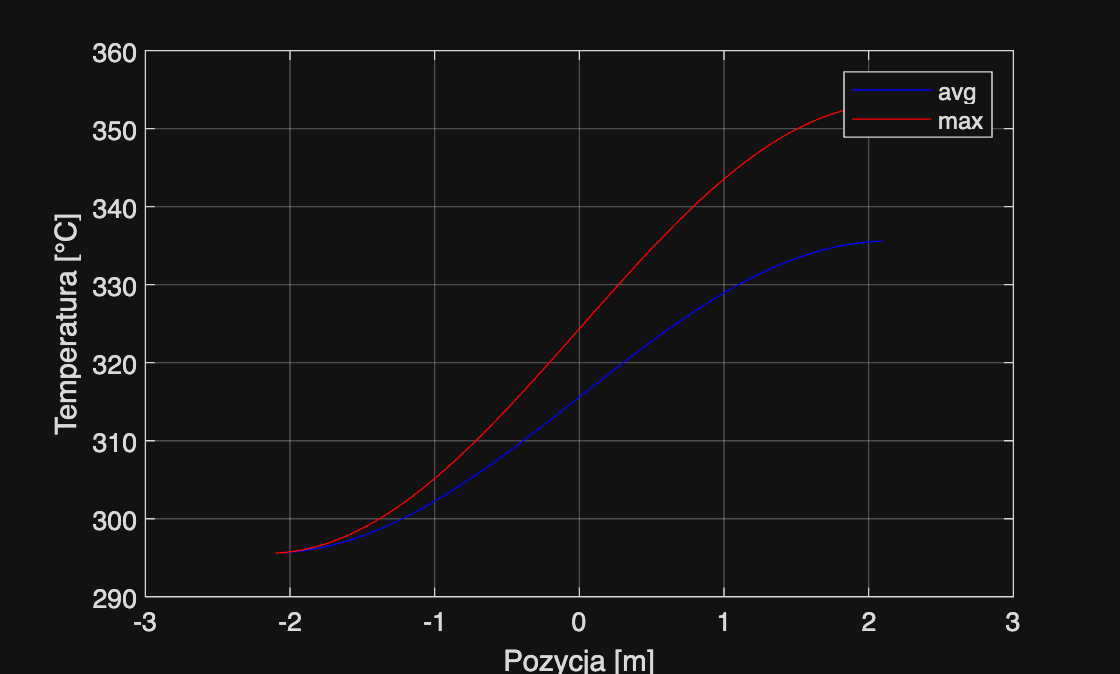

figure(2); grid on; box on; hold on;
xlabel("Pozycja [m]")
ylabel("Temperatura [°C]")
plot(z, TempAvgChannel, "b-")
plot(z, TempHotChannel, "r-")
legend('avg', 'max')